% Tensor Component Analysis (TCA): via Canonical Polyadic Decomposition
% (CPD) - Factor Analysis
clear;

if exist('H:\', 'dir')  % If H:\ exists, assume this is Computer 1
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\BLT';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

elseif exist('G:\', 'dir')  % If G:\ exists, assume this is Computer 2
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\BLT';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

condition = ['BLT'];
file_path = fullfile(input_path,'binepochs filtered ICArej BLTAvgBOS2.set');
EEG = pop_loadset(file_path);

pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...



cpd_input_path = fullfile(output_path,condition);
U_pre = load(fullfile(cpd_input_path,"Bos2_U_pre.mat")).U_pre;
U_post = load(fullfile(cpd_input_path,"Bos2_U_post.mat")).U_post;


fs = EEG.srate; % Sampling rate
time_vector = linspace(-0.5, 3, size(EEG.data, 2)); % Time axis (-500ms to 3000ms)

% - Bandpass filter different EEG bands (theta, alpha, beta, gamma): Here
% we will first focus on beta for its role in attention.
epoch_trials = 1:2:EEG.trials; % Select odd trials
num_trials = length(epoch_trials);

% data = EEG.data(:, :, epoch_trials);
% 
% % Bandpass filter beta band (13-30 Hz)
% beta_band = [13 30];
% beta_signal = zeros(size(data)); % Preallocate
% for epoch = 1:size(data, 3)
%     beta_signal(:,:,epoch) = bandpass(data(:,:,epoch)', beta_band, fs)'; % ch x time x trial
% end
% 
% Define pre- and post-stimulus time windows (400ms before and after stimulus onset at 1020ms)
% 512 sample/sec x 0.4 sec = 204.8
% Define pre-stimulus window (same for both conditions)
pre_window = [-0.4, 0];
post_window = [0, 0.4];

% % Convert time to indices
pre_idx = find(time_vector >= pre_window(1) & time_vector <= pre_window(2));
post_idx = find(time_vector >= post_window(1) & time_vector <= post_window(2));

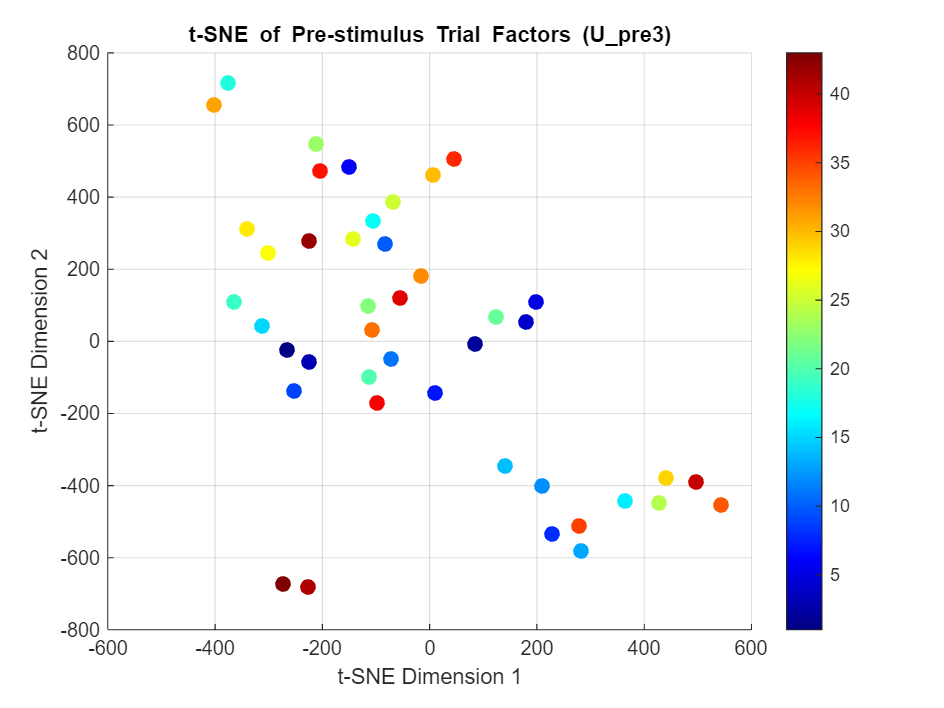

% Trial Factor analysis: t-SNE clustering

% t-SNE clustering on trial factors U_pre{3} and U_post{3}

% Parameters for t-SNE
perplexity = 5; % Default perplexity - adjust based on your number of trials, n/3, 60/3 =20
num_dims = 2;    % 2D visualization

% t-SNE for pre-stimulus trial factors
% Transpose the matrix so each row represents a trial
trial_factors_pre = U_pre{3}';
Y_pre_trial = tsne(trial_factors_pre, 'Perplexity', min(perplexity, size(trial_factors_pre, 1)-1), 'NumDimensions', num_dims);

% t-SNE for post-stimulus trial factors
trial_factors_post = U_post{3}';
Y_post_trial = tsne(trial_factors_post, 'Perplexity', min(perplexity, size(trial_factors_post, 1)-1), 'NumDimensions', num_dims);

% Plot pre-stimulus t-SNE results
figure('Position', [100, 100, 800, 600]);
scatter(Y_pre_trial(:,1), Y_pre_trial(:,2), 50, 1:size(Y_pre_trial,1), 'filled');
colormap(jet);
colorbar;
title('t-SNE of Pre-stimulus Trial Factors (U\_pre{3})');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
grid on;

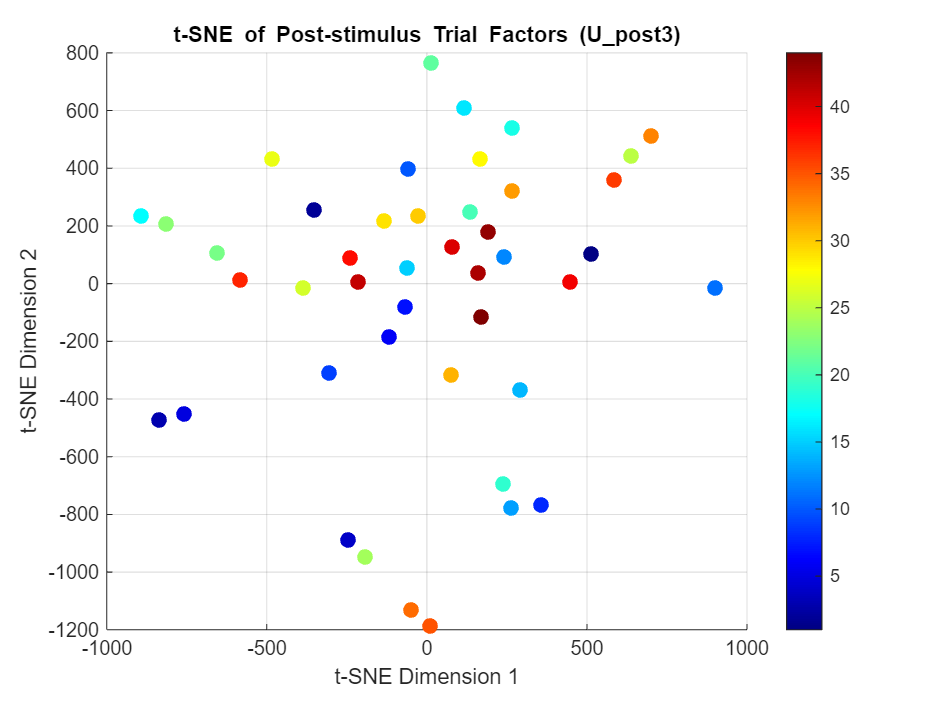


% Plot post-stimulus t-SNE results
figure('Position', [100, 100, 800, 600]);
scatter(Y_post_trial(:,1), Y_post_trial(:,2), 50, 1:size(Y_post_trial,1), 'filled');
colormap(jet);
colorbar;
title('t-SNE of Post-stimulus Trial Factors (U\_post{3})');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
grid on;

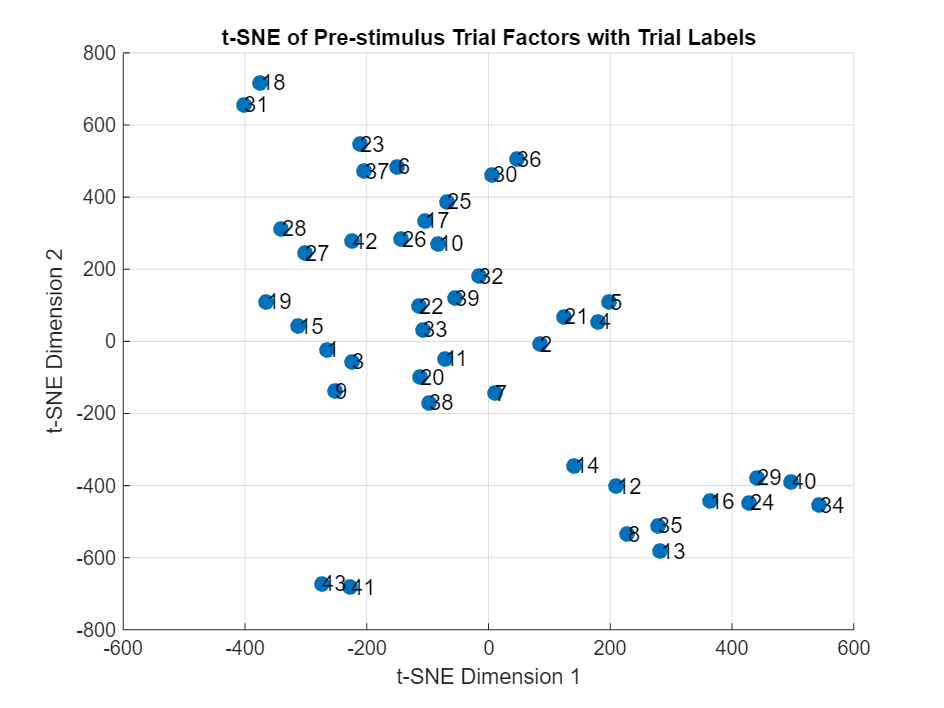


% Alternative visualization: Plot with trial numbers as labels
figure('Position', [100, 100, 800, 600]);
scatter(Y_pre_trial(:,1), Y_pre_trial(:,2), 50, 'filled');
title('t-SNE of Pre-stimulus Trial Factors with Trial Labels');
xlabel('t-SNE Dimension 1'); 
ylabel('t-SNE Dimension 2');
grid on;
% Add trial numbers as text labels (may be crowded with many trials)
for i = 1:size(Y_pre_trial, 1)
    text(Y_pre_trial(i,1), Y_pre_trial(i,2), num2str(i), 'FontSize', 10);
end

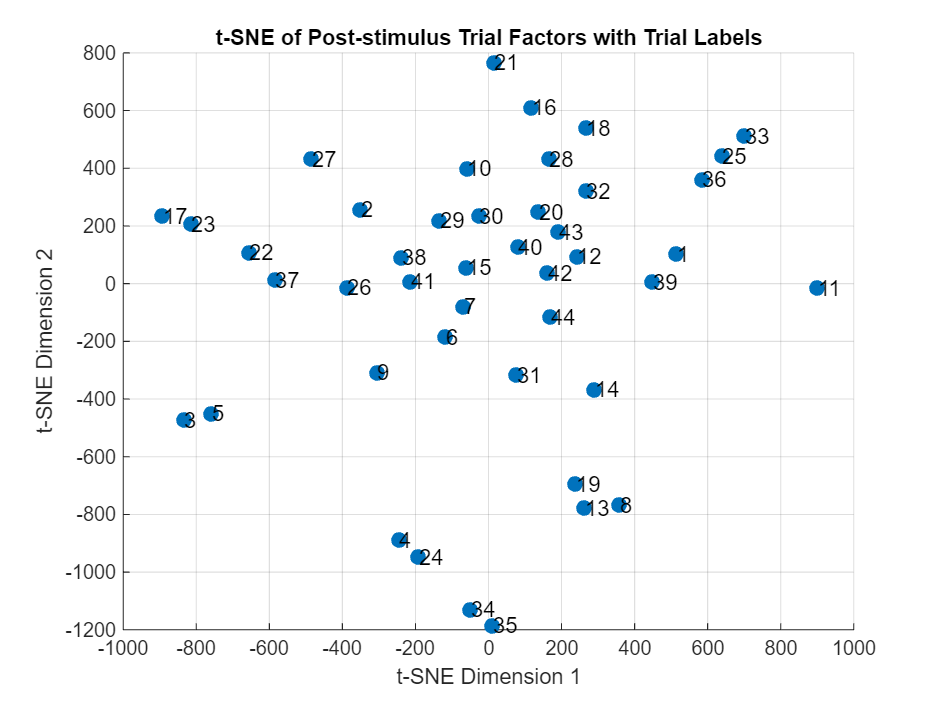


figure('Position', [100, 100, 800, 600]);
scatter(Y_post_trial(:,1), Y_post_trial(:,2), 50, 'filled');
title('t-SNE of Post-stimulus Trial Factors with Trial Labels');
xlabel('t-SNE Dimension 1'); 
ylabel('t-SNE Dimension 2');
grid on;
% Add trial numbers as text labels (may be crowded with many trials)
for i = 1:size(Y_post_trial, 1)
    text(Y_post_trial(i,1), Y_post_trial(i,2), num2str(i), 'FontSize', 10);
end

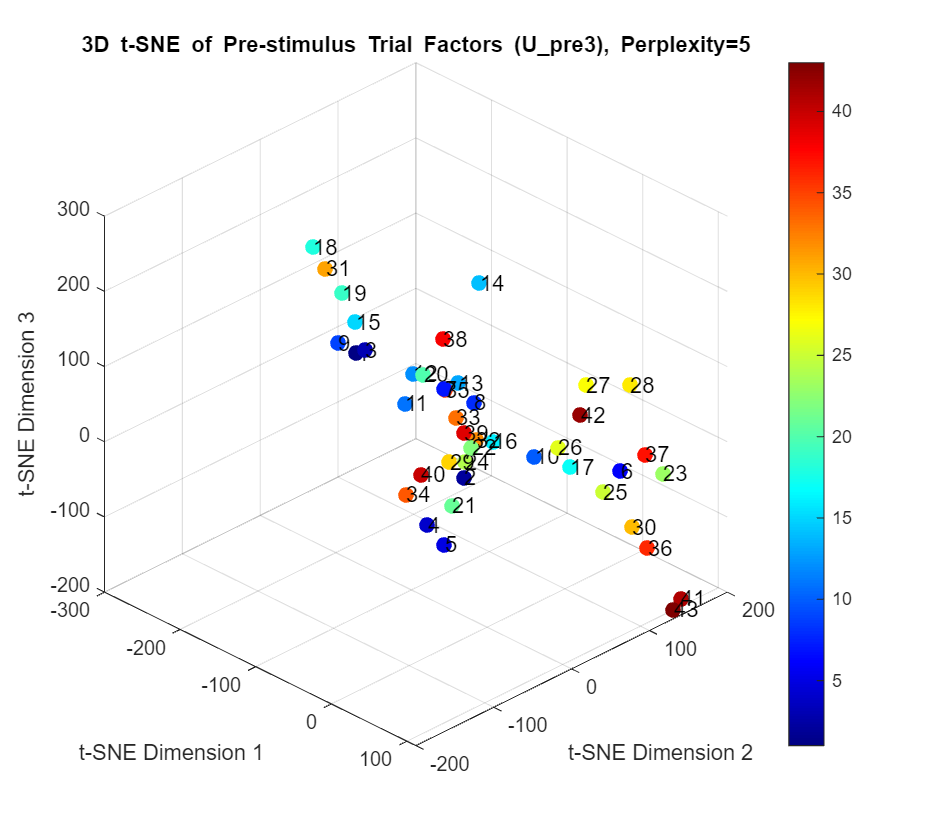


% t-SNE clustering on trial factors U_pre{3} and U_post{3} with 3D visualization

% Parameters for t-SNE
% perplexity = 10;  % Set perplexity to 60 as requested
num_dims = 3;     % 3D visualization

% t-SNE for pre-stimulus trial factors
% Transpose the matrix so each row represents a trial
trial_factors_pre = U_pre{3}';
Y_pre_trial = tsne(trial_factors_pre, 'Perplexity', min(perplexity, size(trial_factors_pre, 1)-1), 'NumDimensions', num_dims);

% t-SNE for post-stimulus trial factors
trial_factors_post = U_post{3}';
Y_post_trial = tsne(trial_factors_post, 'Perplexity', min(perplexity, size(trial_factors_post, 1)-1), 'NumDimensions', num_dims);

% 3D Plot for pre-stimulus t-SNE results with trial labels
figure('Position', [100, 100, 900, 800]);
scatter3(Y_pre_trial(:,1), Y_pre_trial(:,2), Y_pre_trial(:,3), 50, 1:size(Y_pre_trial,1), 'filled');
colormap(jet);
colorbar;
title(['3D t-SNE of Pre-stimulus Trial Factors (U\_pre{3}), Perplexity=' num2str(perplexity)]);
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
zlabel('t-SNE Dimension 3');
grid on;

% Add trial numbers as text labels
for i = 1:size(Y_pre_trial, 1)
    text(Y_pre_trial(i,1), Y_pre_trial(i,2), Y_pre_trial(i,3), num2str(i), 'FontSize', 10);
end

% Improve the view angle for better visualization
view(45, 30);

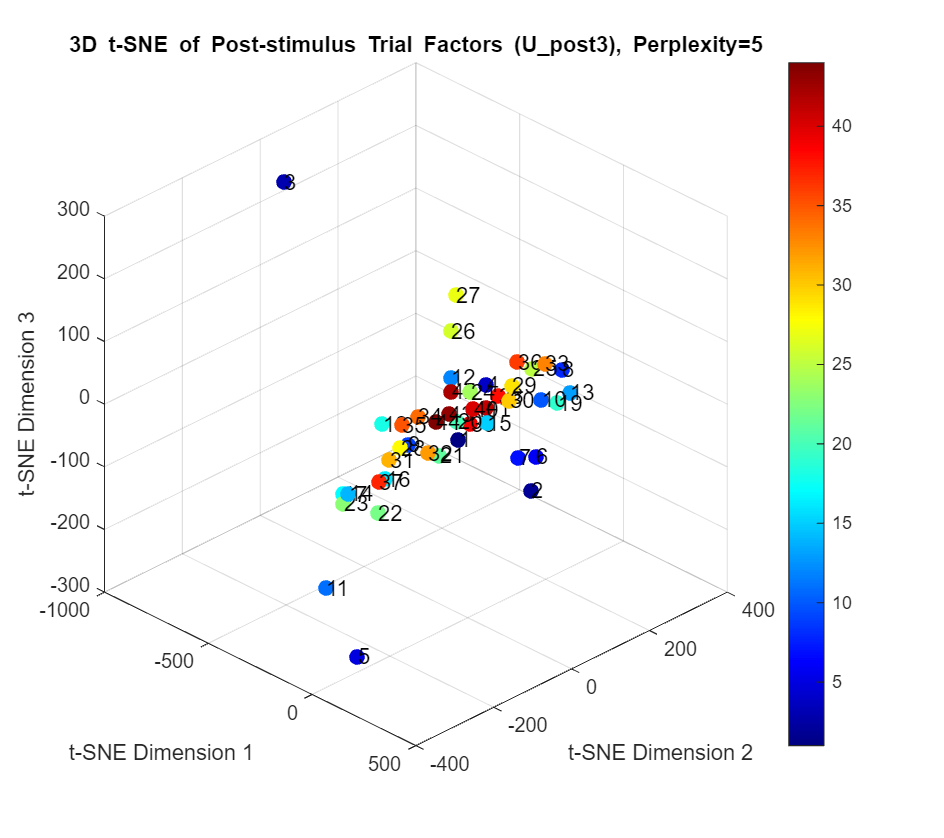


% 3D Plot for post-stimulus t-SNE results with trial labels
figure('Position', [100, 100, 900, 800]);
scatter3(Y_post_trial(:,1), Y_post_trial(:,2), Y_post_trial(:,3), 50, 1:size(Y_post_trial,1), 'filled');
colormap(jet);
colorbar;
title(['3D t-SNE of Post-stimulus Trial Factors (U\_post{3}), Perplexity=' num2str(perplexity)]);
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
zlabel('t-SNE Dimension 3');
grid on;

% Add trial numbers as text labels
for i = 1:size(Y_post_trial, 1)
    text(Y_post_trial(i,1), Y_post_trial(i,2), Y_post_trial(i,3), num2str(i), 'FontSize', 10);
end

% Improve the view angle for better visualization
view(45, 30);

% Add ability to rotate the 3D plots
rotate3d on;

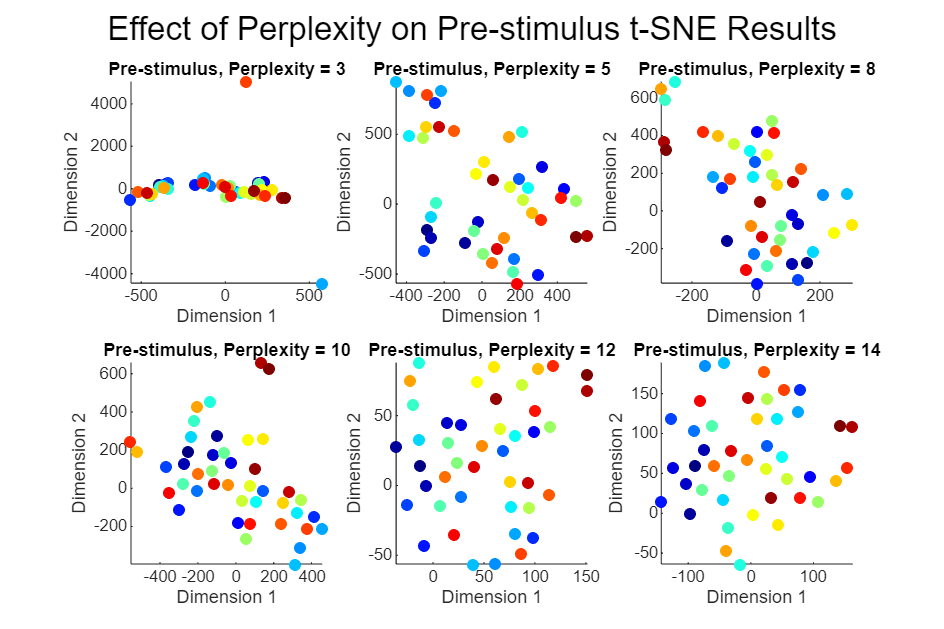

% Systematic approach to selecting perplexity for trials
perplexity_values = [3, 5, 8, 10, 12, 14];
num_dims = 2;  % Using 2D for easier comparison

% Preallocate cell arrays to store results
Y_pre_results_trial = cell(length(perplexity_values), 1);
Y_post_results_trial = cell(length(perplexity_values), 1);

% Run t-SNE with different perplexity values
for i = 1:length(perplexity_values)
    perp = perplexity_values(i);
    effective_perp_trial = min(perp, size(trial_factors_pre, 1)-1);
    
    % Pre-stimulus
    Y_pre_results_trial{i} = tsne(trial_factors_pre, 'Perplexity', effective_perp_trial, 'NumDimensions', num_dims);
    
    % Post-stimulus
    Y_post_results_trial{i} = tsne(trial_factors_post, 'Perplexity', effective_perp_trial, 'NumDimensions', num_dims);
end

% Create a grid of plots for pre-stimulus results
figure('Position', [100, 100, 1200, 800]);
for i = 1:length(perplexity_values)
    subplot(2, 3, i);
    scatter(Y_pre_results_trial{i}(:,1), Y_pre_results_trial{i}(:,2), 30, 1:size(Y_pre_results_trial{i},1), 'filled');
    title(['Pre-stimulus, Perplexity = ', num2str(perplexity_values(i))]);
    xlabel('Dimension 1');
    ylabel('Dimension 2');
    colormap(jet);
    axis tight;
end
sgtitle('Effect of Perplexity on Pre-stimulus t-SNE Results');

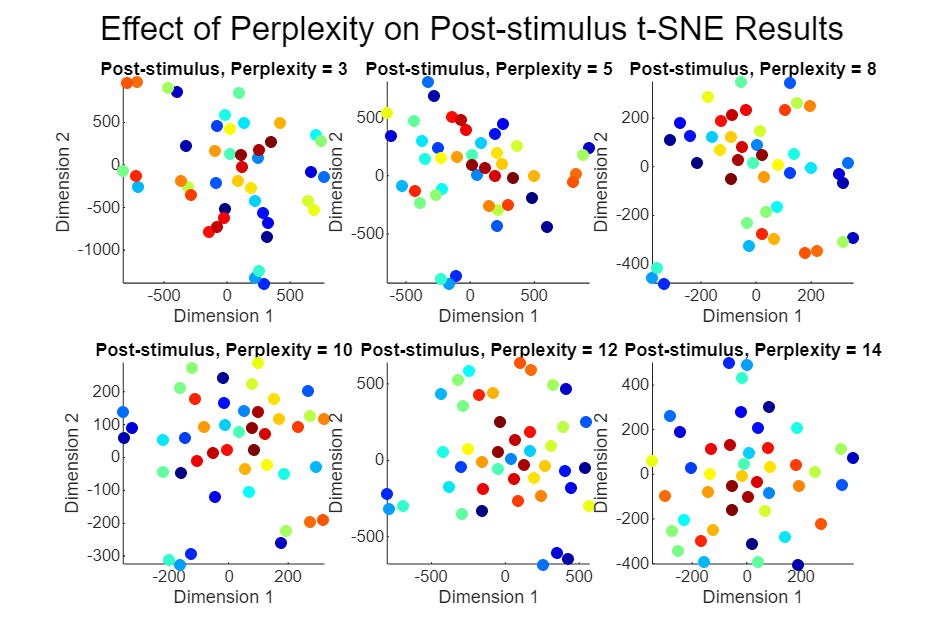


% Create a grid of plots for post-stimulus results
figure('Position', [100, 100, 1200, 800]);
for i = 1:length(perplexity_values)
    subplot(2, 3, i);
    scatter(Y_post_results_trial{i}(:,1), Y_post_results_trial{i}(:,2), 30, 1:size(Y_post_results_trial{i},1), 'filled');
    title(['Post-stimulus, Perplexity = ', num2str(perplexity_values(i))]);
    xlabel('Dimension 1');
    ylabel('Dimension 2');
    colormap(jet);
    axis tight;
end
sgtitle('Effect of Perplexity on Post-stimulus t-SNE Results');

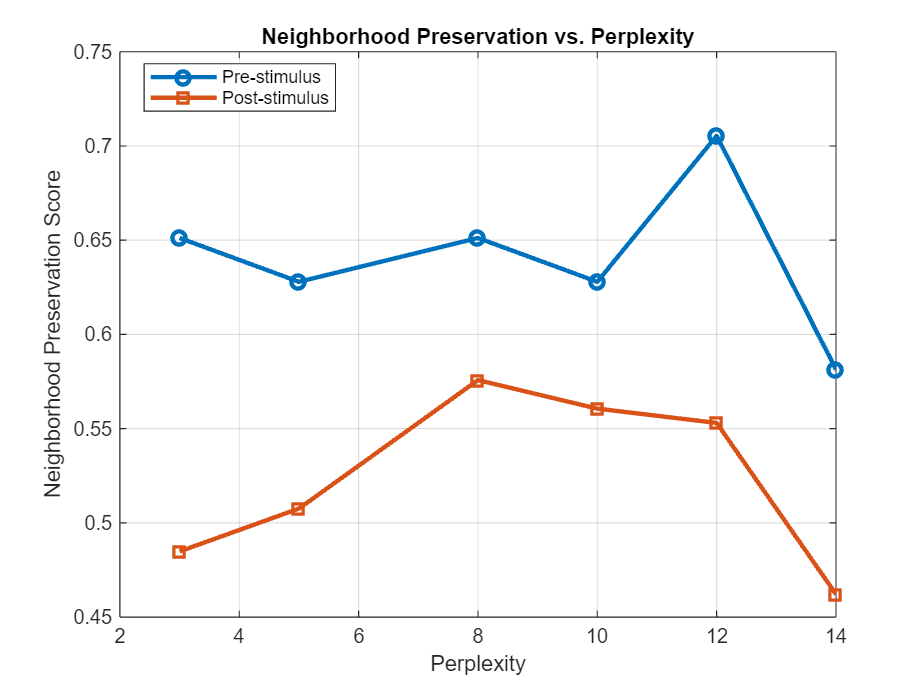

% % Alternative cluster quality evaluation using DBSCAN
% epsilon_values = [0.5, 1, 2]; % Multiple epsilon values to try
% best_silhouette_pre = zeros(length(perplexity_values), 1);
% best_silhouette_post = zeros(length(perplexity_values), 1);
% 
% for i = 1:length(perplexity_values)
%     max_sil_pre = -1;
%     max_sil_post = -1;
% 
%     % Try different epsilon values for DBSCAN
%     for eps_val = epsilon_values
%         % Pre-stimulus
%         try
%             % Normalize data before clustering
%             data_pre = Y_pre_results_trial{i};
%             data_pre = (data_pre - mean(data_pre)) ./ std(data_pre);
% 
%             idx_pre = dbscan(data_pre, eps_val, 5);
%             % Only calculate silhouette if we have more than one cluster 
%             % and no noise points (labeled as -1)
%             if length(unique(idx_pre)) > 1 && ~any(idx_pre == -1)
%                 sil_pre = mean(silhouette(data_pre, idx_pre));
%                 max_sil_pre = max(max_sil_pre, sil_pre);
%             end
%         catch
%             % Skip this epsilon value if an error occurs
%         end
% 
%         % Post-stimulus
%         try
%             data_post = Y_post_results_trial{i};
%             data_post = (data_post - mean(data_post)) ./ std(data_post);
% 
%             idx_post = dbscan(data_post, eps_val, 5);
%             if length(unique(idx_post)) > 1 && ~any(idx_post == -1)
%                 sil_post = mean(silhouette(data_post, idx_post));
%                 max_sil_post = max(max_sil_post, sil_post);
%             end
%         catch
%             % Skip this epsilon value if an error occurs
%         end
%     end
% 
%     best_silhouette_pre(i) = max_sil_pre;
%     best_silhouette_post(i) = max_sil_post;
% end
% 
% % Plot best silhouette scores
% figure;
% valid_pre = best_silhouette_pre > 0;
% valid_post = best_silhouette_post > 0;
% 
% plot(perplexity_values(valid_pre), best_silhouette_pre(valid_pre), 'o-', 'LineWidth', 2, 'DisplayName', 'Pre-stimulus');
% hold on;
% plot(perplexity_values(valid_post), best_silhouette_post(valid_post), 's-', 'LineWidth', 2, 'DisplayName', 'Post-stimulus');
% xlabel('Perplexity');
% ylabel('Best Silhouette Score');
% title('Cluster Quality vs. Perplexity (DBSCAN)');
% legend('Location', 'best');
% grid on;
% A simpler approach: evaluate local neighborhood preservation
k_neighbors = 3; % Number of neighbors to consider
% Calculate neighborhood preservation for each perplexity
neighborhood_scores_pre = zeros(length(perplexity_values), 1);
neighborhood_scores_post = zeros(length(perplexity_values), 1);

for i = 1:length(perplexity_values)
    neighborhood_scores_pre(i) = calculate_neighborhood_preservation(trial_factors_pre, Y_pre_results_trial{i}, k_neighbors);
    neighborhood_scores_post(i) = calculate_neighborhood_preservation(trial_factors_post, Y_post_results_trial{i}, k_neighbors);
end

% Plot neighborhood preservation scores
figure;
plot(perplexity_values, neighborhood_scores_pre, 'o-', 'LineWidth', 2, 'DisplayName', 'Pre-stimulus');
hold on;
plot(perplexity_values, neighborhood_scores_post, 's-', 'LineWidth', 2, 'DisplayName', 'Post-stimulus');
xlabel('Perplexity');
ylabel('Neighborhood Preservation Score');
title('Neighborhood Preservation vs. Perplexity');
legend('Location', 'best');
grid on;

Testing n_neighbors=13, min_dist=0.10 (1/

UMAP & UST (v4.4), Herzenberg Lab, Stanford University,
	Original inventors: Leland McInnes, John Healy & James Melville
	MATLAB/C++/Java/Python implementors/evolvers: Connor Meehan, Jonathan Ebrahimian & Stephen Meehan


ans =

	javahandle_withcallbacks.edu.stanford.facs.swing.ImageButton

Parallelizing UMAP with MATLAB's 24 assigned logical cores for nn_descent_tasks, sgd_tasks


 Running basic (ub) reduction, v4.4
(ub=basic, us=supervised, ubt=template, ust=supervised template)
UMAP(method=MEX, n_neighbors=13, n_components=2, metric='euclidean', n_epochs=[], learning_rate=1, init=spectral, min_dist=0.1, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=1.57694357028599, b=0.895060673920128, randomize=true, target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]


ans =   Contour with properties:

    EdgeColor: [0.5000 0.5000 0.6000]
    LineStyle: '-'
    LineWidth: 1
    FaceColor: 'none'
    LevelList: [0.0330 0.0460 0.0545 0.0624 0.0687 0.0765 0.0844 0.0930 0.1070 0.1329]
        XData: [256×256 double]
        YData: [256×256 double]
        ZData: [256×256 double]

  Show all properties


UMAP reduction finished (cost 1.60 secs)
 Finished basic (ub) reduction


UMAP & UST (v4.4), Herzenberg Lab, Stanford University,
	Original inventors: Leland McInnes, John Healy & James Melville
	MATLAB/C++/Java/Python implementors/evolvers: Connor Meehan, Jonathan Ebrahimian & Stephen Meehan



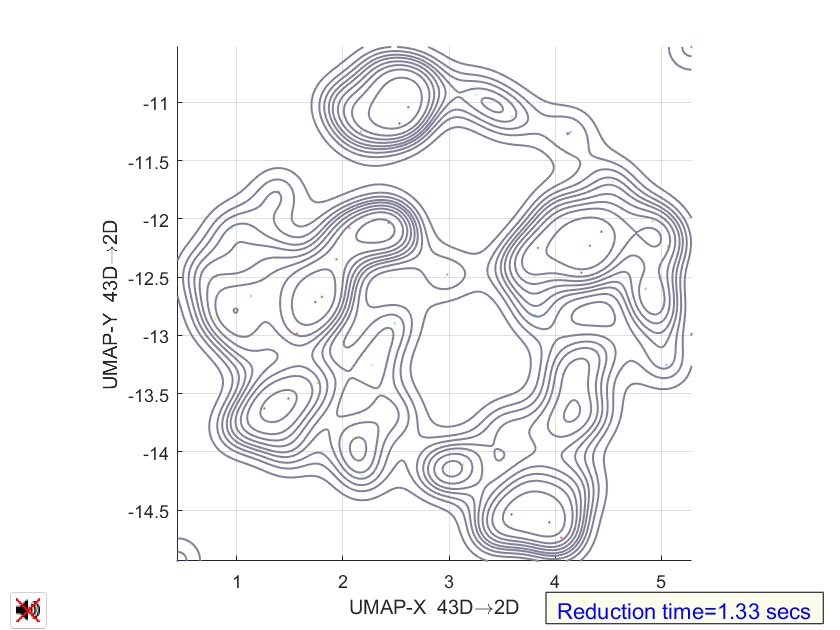


ans =

	javahandle_withcallbacks.edu.stanford.facs.swing.ImageButton

Parallelizing UMAP with MATLAB's 24 assigned logical cores for nn_descent_tasks, sgd_tasks


 Running basic (ub) reduction, v4.4
(ub=basic, us=supervised, ubt=template, ust=supervised template)
UMAP(method=MEX, n_neighbors=13, n_components=2, metric='euclidean', n_epochs=[], learning_rate=1, init=spectral, min_dist=0.1, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=1.57694357028599, b=0.895060673920128, randomize=true, target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]


ans =   Contour with properties:

    EdgeColor: [0.5000 0.5000 0.6000]
    LineStyle: '-'
    LineWidth: 1
    FaceColor: 'none'
    LevelList: [0.0342 0.0479 0.0566 0.0632 0.0692 0.0766 0.0840 0.0931 0.1067 0.1436]
        XData: [256×256 double]
        YData: [256×256 double]
        ZData: [256×256 double]

  Show all properties


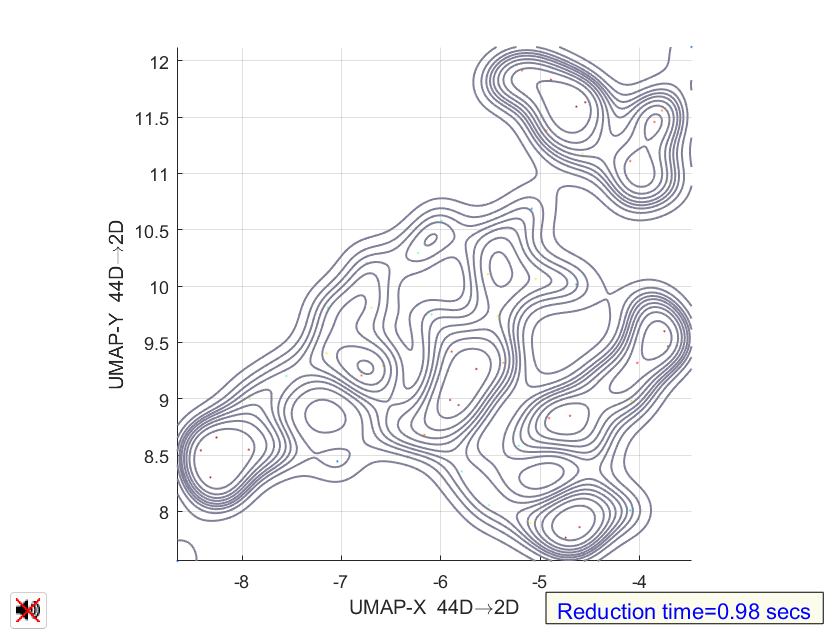

UMAP reduction finished (cost 1.22 secs)
 Finished basic (ub) reduction


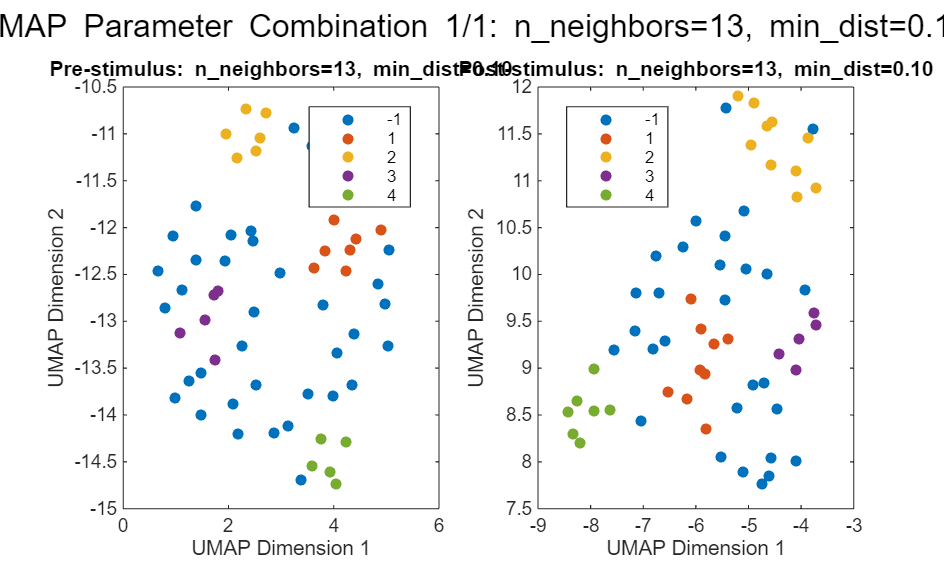

% Trial factor analysis using UMAP
% First, make sure you have the UMAP MATLAB package installed
% You can install it via: 
% https://www.mathworks.com/matlabcentral/fileexchange/71902-uniform-manifold-approximation-and-projection-umap

% Define parameter combinations to test
% n_neighbors_values = [3, 8, 13];
% min_dist_values = [0.1, 0.5, 0.8]; % Changed 1.0 to 0.8 to avoid potential boundary issues
n_neighbors_values = [13];
min_dist_values = [0.1]; %
% Number of combinations
num_combinations = length(n_neighbors_values) * length(min_dist_values);

% Create structure to store results
results = struct('n_neighbors', {}, 'min_dist', {}, ...
                'umap_pre', {}, 'umap_post', {}, ...
                'pre_clusters', {}, 'post_clusters', {}, ...
                'status', {});

% Set consistent random seed for reproducibility
rng(42);

% Prepare figure for visualization
figure('Position', [100, 100, 1200, 800]);

% Counter for subplot positions
combo_idx = 1;

% Loop through all parameter combinations
for i = 1:length(n_neighbors_values)
    for j = 1:length(min_dist_values)
        % Current parameter set
        curr_n_neighbors = n_neighbors_values(i);
        curr_min_dist = min_dist_values(j);
        
        % Initialize current result entry
        curr_result = struct('n_neighbors', curr_n_neighbors, ...
                           'min_dist', curr_min_dist, ...
                           'umap_pre', [], 'umap_post', [], ...
                           'pre_clusters', [], 'post_clusters', [], ...
                           'status', 'pending');
        
        % Display current parameter combination
        fprintf('Testing n_neighbors=%d, min_dist=%.2f (%d/%d)\n', ...
                curr_n_neighbors, curr_min_dist, num_combinations);
        
        % Try running UMAP with current parameters
        try
            % Run UMAP on pre-condition trial factors
            [umap_pre, umap_params] = run_umap(U_pre{3}, 'n_neighbors', curr_n_neighbors, ...
                                             'min_dist', curr_min_dist, ...
                                             'n_components', 2, ...
                                             'seed', 42);
            
            % Run UMAP on post-condition trial factors
            [umap_post, ~] = run_umap(U_post{3}, 'n_neighbors', curr_n_neighbors, ...
                                    'min_dist', curr_min_dist, ...
                                    'n_components', 2, ...
                                    'seed', 42);
            
            % Store UMAP results
            curr_result.umap_pre = umap_pre;
            curr_result.umap_post = umap_post;
            
            % Apply DBSCAN clustering
            epsilon = 0.5;  % You might want to adjust this for each parameter set
            minPts = 5;
            
            curr_result.pre_clusters = dbscan(umap_pre, epsilon, minPts);
            curr_result.post_clusters = dbscan(umap_post, epsilon, minPts);
            
            % Mark as successful
            curr_result.status = 'success';
            
           % Create a new figure for this parameter combination
            fig = figure('Position', [100, 100, 1000, 600]);
            
            % Pre-stimulus plot
            subplot(1, 2, 1);
            gscatter(umap_pre(:,1), umap_pre(:,2), curr_result.pre_clusters);
            title(sprintf('Pre-stimulus: n\\_neighbors=%d, min\\_dist=%.2f', curr_n_neighbors, curr_min_dist));
            xlabel('UMAP Dimension 1');
            ylabel('UMAP Dimension 2');
            
            % Post-stimulus plot
            subplot(1, 2, 2);
            gscatter(umap_post(:,1), umap_post(:,2), curr_result.post_clusters);
            title(sprintf('Post-stimulus: n\\_neighbors=%d, min\\_dist=%.2f', curr_n_neighbors, curr_min_dist));
            xlabel('UMAP Dimension 1');
            ylabel('UMAP Dimension 2');
            
            % Add overall title
            sgtitle(sprintf('UMAP Parameter Combination %d/%d: n\\_neighbors=%d, min\\_dist=%.2f', ...
                combo_idx, num_combinations, curr_n_neighbors, curr_min_dist));
            
            % % Save the figure
            % fig_filename = sprintf('umap_params_n%d_d%.2f.png', curr_n_neighbors, curr_min_dist);
            % saveas(fig, fig_filename);
            % 
            % % Optional: close the figure if you don't want too many open at once
            % close(fig);
            
        catch e
            % Handle errors
            fprintf('Error with n_neighbors=%d, min_dist=%.2f: %s\n', ...
                    curr_n_neighbors, curr_min_dist, e.message);
            curr_result.status = sprintf('error: %s', e.message);
        end
        
        % Store current result
        results(end+1) = curr_result;
        
        % Increment combination counter
        combo_idx = combo_idx + 1;
    end
end


% Save all results to a MAT file
save('umap_parameter_exploration.mat', 'results');

% Display summary
fprintf('\nParameter Testing Summary:\n');


Parameter Testing Summary:


fprintf('------------------------\n');

------------------------


for i = 1:length(results)
    fprintf('n_neighbors=%d, min_dist=%.2f: %s\n', ...
            results(i).n_neighbors, results(i).min_dist, results(i).status);
end

n_neighbors=13, min_dist=0.10: success


% Function to calculate neighborhood preservation

function score = calculate_neighborhood_preservation(orig_data, embedded_data, k)
    % Get the k nearest neighbors in original space
    [~, orig_idx] = pdist2(orig_data, orig_data, 'euclidean', 'Smallest', k+1);
    orig_idx = orig_idx(2:end, :)'; % Remove self and transpose
    
    % Get the k nearest neighbors in embedded space
    [~, emb_idx] = pdist2(embedded_data, embedded_data, 'euclidean', 'Smallest', k+1);
    emb_idx = emb_idx(2:end, :)'; % Remove self and transpose
    
    % Calculate overlap between neighborhoods
    overlap = 0;
    for i = 1:size(orig_data, 1)
        overlap = overlap + length(intersect(orig_idx(i,:), emb_idx(i,:)));
    end
    
    % Return average percentage of preserved neighbors
    score = overlap / (k * size(orig_data, 1));
end